# Feedback FOPDT Models

Daniel Anthony Barrett

21 June 2023

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Feedback FOPDT Models

Fit FOPDT models to the copper solvent extraction model to use for the feedback controller tuning

## Setup

### MATLAB Simulink

clear;
clc;
gamma_max = 2000; 

### Plot colours

maroon = '#A2142F';
blue   = '#0072BD';

## Step in v_LE

### Read data

vLE_step_data = readtable('controller_tuning\data\feedback\vLE_step_feedback7.csv'); %'); feedback_step_v_LE_control.csv'

### Extract data

% model time
vLE_step.time = vLE_step_data.Time; 

% valve position data
vLE_step.vLE = vLE_step_data.vLE_control; %v_LE_control; %
vLE_step.vLO = vLE_step_data.vLO_control; %v_LO_control; %

% controlled variables data
vLE_step.cLO = vLE_step_data.cLO_measured; %c_LO_measured; %;
vLE_step.cRE = vLE_step_data.cRE_measured; %c_RE_measured; %

### Preprocess

% deviation variable form
vLE_step.vLE_prime = vLE_step.vLE-vLE_step.vLE(1);
vLE_step.vLO_prime = vLE_step.vLO-vLE_step.vLO(1);
vLE_step.cLO_prime = vLE_step.cLO-vLE_step.cLO(1);
vLE_step.cRE_prime = vLE_step.cRE-vLE_step.cRE(1);

% time step size
vLE_step.deltaT = vLE_step.time(2) - vLE_step.time(1);

% time in hours
vLE_step.timeH = vLE_step.time/(60*60);

### cLO change

### FOPDT model

for gamma = 0:gamma_max*4
    
    % system set up
    vLE_step.A = [vLE_step.cLO_prime((1+gamma):(end-1)), vLE_step.vLE_prime(1:(end-1-gamma))];
    vLE_step.z = vLE_step.cLO_prime((2+gamma):end);
    
    % linear regression
    w = vLE_step.A\vLE_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    vLE_step.cLO_p = vLE_step.A*w;
    
    % calculate MSE 
    vLE_step.MSE_cLO(gamma+1) = mean((vLE_step.cLO_p - vLE_step.z).^2);
    
    % calculate transfer function 
    vLE_step.Kp_cLO(gamma+1) = b/(1-a);
    vLE_step.tau_cLO(gamma+1) = -vLE_step.deltaT/log(a);
    vLE_step.theta_cLO(gamma+1) = gamma*vLE_step.deltaT;
end

#### Find optimal gamma values

% index of optimal gamma
vLE_step.opt_gamma_index_cLO = find(vLE_step.MSE_cLO == min(vLE_step.MSE_cLO));
% optimal transfer function values
vLE_step.opt_gamma_cLO = vLE_step.opt_gamma_index_cLO - 1;
vLE_step.opt_Kp_cLO = vLE_step.Kp_cLO(vLE_step.opt_gamma_index_cLO);
vLE_step.opt_tau_cLO = vLE_step.tau_cLO(vLE_step.opt_gamma_index_cLO);
vLE_step.opt_theta_cLO = vLE_step.theta_cLO(vLE_step.opt_gamma_index_cLO);

#### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = vLE_step.opt_Kp_cLO;
simulink_tau = vLE_step.opt_tau_cLO;
simulink_theta = vLE_step.opt_theta_cLO;

% run Simulink model
simulink_input = [vLE_step.time vLE_step.vLE_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
vLE_step.FOPDT_fit_cLO = simulink_output.results.Data;
vLE_step.FOPDT_time_cLO = simulink_output.tout;
vLE_step.FOPDT_timeH_cLO = simulink_output.tout/(60*60);

#### Plot cLO response to vLE change

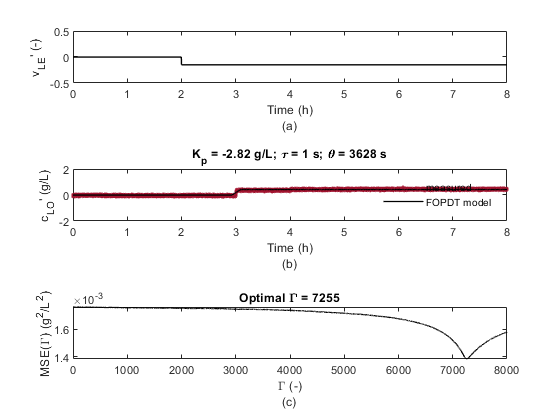

fig = figure(1);

% plot vLE
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(vLE_step.timeH, vLE_step.vLE_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("v_{LE}' (-)");
xlim([0 vLE_step.FOPDT_timeH_cLO(end)]);
ylim([-0.5 0.5]);

% plot cLO measured
ax2 = nexttile(tlo,2);
plot(vLE_step.timeH, vLE_step.cLO_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(vLE_step.FOPDT_timeH_cLO, vLE_step.FOPDT_fit_cLO, 'k-', 'LineWidth', 1);
hold off
vLE_step.cLO_title = sprintf('K_p = %.2f g/L; \\tau = %.0f s; \\theta = %.0f s', vLE_step.opt_Kp_cLO, vLE_step.opt_tau_cLO, vLE_step.opt_theta_cLO);
title(vLE_step.cLO_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{LO}' (g/L)");
xlim([0 vLE_step.FOPDT_timeH_cLO(end)]);
ylim([-2 2]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max*4], vLE_step.MSE_cLO, 'k-', 'LineWidth', 1);
vLE_step.cLO_MSE_title = sprintf('Optimal \\Gamma = %.0f', vLE_step.opt_gamma_cLO);
title(vLE_step.cLO_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max*4]);

% save figure
print('controller_tuning/output/feedback/vLE_step_cLO_model', '-dpng', '-r600');

**cRE change**

**FOPDT model**

for gamma = 0:gamma_max
    
    % system set up
    vLE_step.A = [vLE_step.cRE_prime((1+gamma):(end-1)), vLE_step.vLE_prime(1:(end-1-gamma))];
    vLE_step.z = vLE_step.cRE_prime((2+gamma):end);
    
    % linear regression
    w = vLE_step.A\vLE_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    vLE_step.cRE_p = vLE_step.A*w;
    
    % calculate MSE 
    vLE_step.MSE_cRE(gamma+1) = mean((vLE_step.cRE_p - vLE_step.z).^2);
    
    % calculate transfer function 
    vLE_step.Kp_cRE(gamma+1) = b/(1-a);
    vLE_step.tau_cRE(gamma+1) = -vLE_step.deltaT/log(a);
    vLE_step.theta_cRE(gamma+1) = gamma*vLE_step.deltaT;
end

**Find optimal gamma values**

% index of optimal gamma
vLE_step.opt_gamma_index_cRE = find(vLE_step.MSE_cRE == min(vLE_step.MSE_cRE));
% optimal transfer function values
vLE_step.opt_gamma_cRE = vLE_step.opt_gamma_index_cRE - 1;
vLE_step.opt_Kp_cRE = vLE_step.Kp_cRE(vLE_step.opt_gamma_index_cRE);
vLE_step.opt_tau_cRE = vLE_step.tau_cRE(vLE_step.opt_gamma_index_cRE);
vLE_step.opt_theta_cRE = vLE_step.theta_cRE(vLE_step.opt_gamma_index_cRE);

**Simulate transfer function on Simulink**

% setup simulink transfer function values
simulink_Kp = vLE_step.opt_Kp_cRE;
simulink_tau = vLE_step.opt_tau_cRE;
simulink_theta = vLE_step.opt_theta_cRE;

% run Simulink model
simulink_input = [vLE_step.time vLE_step.vLE_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
vLE_step.FOPDT_fit_cRE = simulink_output.results.Data;
vLE_step.FOPDT_time_cRE = simulink_output.tout;
vLE_step.FOPDT_timeH_cRE = simulink_output.tout/(60*60);

**Plot cRE response to vLE change**

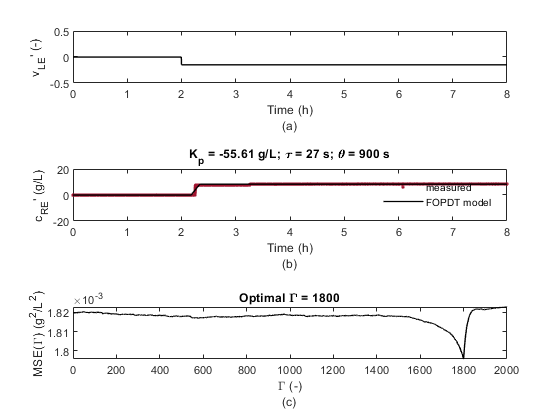

fig = figure(2);

% plot vLE
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(vLE_step.timeH, vLE_step.vLE_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("v_{LE}' (-)");
xlim([0 vLE_step.FOPDT_timeH_cRE(end)]);
ylim([-0.5 0.5]);

% plot cRE measured
ax2 = nexttile(tlo,2);
plot(vLE_step.timeH, vLE_step.cRE_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(vLE_step.FOPDT_timeH_cRE, vLE_step.FOPDT_fit_cRE, 'k-', 'LineWidth', 1);
hold off
vLE_step.cRE_title = sprintf('K_p = %.2f g/L; \\tau = %.0f s; \\theta = %.0f s', vLE_step.opt_Kp_cRE, vLE_step.opt_tau_cRE, vLE_step.opt_theta_cRE);
title(vLE_step.cRE_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{RE}' (g/L)");
xlim([0 vLE_step.FOPDT_timeH_cRE(end)]);
ylim([-20 20]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max], vLE_step.MSE_cRE, 'k-', 'LineWidth', 1);
vLE_step.cRE_MSE_title = sprintf('Optimal \\Gamma = %.0f', vLE_step.opt_gamma_cRE);
title(vLE_step.cRE_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max]);

% save figure
print('controller_tuning/output/feedback/vLE_step_cRE_model', '-dpng', '-r600');

## Step in v_LO

### Read data

vLO_step_data = readtable('controller_tuning\data\feedback\vLO_step_feedback.csv'); 

### Extract data

% model time
vLO_step.time = vLO_step_data.Time; 

% valve position data
vLO_step.vLE = vLO_step_data.vLE_control; %v_LE_control; %
vLO_step.vLO = vLO_step_data.vLO_control; %v_LO_control; %

% controlled variables data
vLO_step.cLO = vLO_step_data.cLO_measured; %c_LO_measured; %;
vLO_step.cRE = vLO_step_data.cRE_measured; %c_RE_measured; %


### Preprocess

% deviation variable form
vLO_step.vLE_prime = vLO_step.vLE-vLO_step.vLE(1);
vLO_step.vLO_prime = vLO_step.vLO-vLO_step.vLO(1);
vLO_step.cLO_prime = vLO_step.cLO-vLO_step.cLO(1);
vLO_step.cRE_prime = vLO_step.cRE-vLO_step.cRE(1);

% time step size
vLO_step.deltaT = vLO_step.time(2) - vLO_step.time(1);

% time in hours
vLO_step.timeH = vLO_step.time/(60*60);


### cLO change

### FOPDT model

for gamma = 0:gamma_max*2
    
    % system set up
    vLO_step.A = [vLO_step.cLO_prime((1+gamma):(end-1)), vLO_step.vLO_prime(1:(end-1-gamma))];
    vLO_step.z = vLO_step.cLO_prime((2+gamma):end);
    
    % linear regression
    w = vLO_step.A\vLO_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    vLO_step.cLO_p = vLO_step.A*w;
    
    % calculate MSE 
    vLO_step.MSE_cLO(gamma+1) = mean((vLO_step.cLO_p - vLO_step.z).^2);
    
    % calculate transfer function 
    vLO_step.Kp_cLO(gamma+1) = b/(1-a);
    vLO_step.tau_cLO(gamma+1) = -vLO_step.deltaT/log(a);
    vLO_step.theta_cLO(gamma+1) = gamma*vLO_step.deltaT;
end


### Find optimal gamma values

% index of optimal gamma
vLO_step.opt_gamma_index_cLO = find(vLO_step.MSE_cLO == min(vLO_step.MSE_cLO));
% optimal transfer function values
vLO_step.opt_gamma_cLO = vLO_step.opt_gamma_index_cLO - 1;
vLO_step.opt_Kp_cLO = vLO_step.Kp_cLO(vLO_step.opt_gamma_index_cLO);
vLO_step.opt_tau_cLO = vLO_step.tau_cLO(vLO_step.opt_gamma_index_cLO);
vLO_step.opt_theta_cLO = vLO_step.theta_cLO(vLO_step.opt_gamma_index_cLO);


### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = vLO_step.opt_Kp_cLO;
simulink_tau = vLO_step.opt_tau_cLO;
simulink_theta = vLO_step.opt_theta_cLO;

% run Simulink model
simulink_input = [vLO_step.time vLO_step.vLO_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
vLO_step.FOPDT_fit_cLO = simulink_output.results.Data;
vLO_step.FOPDT_time_cLO = simulink_output.tout;
vLO_step.FOPDT_timeH_cLO = simulink_output.tout/(60*60);


### Plot cLO response to vLO change

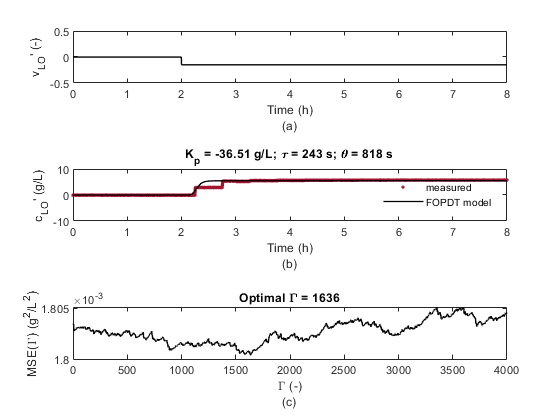

fig = figure(3);

% plot vLO
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(vLO_step.timeH, vLO_step.vLO_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("v_{LO}' (-)");
xlim([0 vLO_step.FOPDT_timeH_cLO(end)]);
ylim([-0.5 0.5]);

% plot cLO measured
ax2 = nexttile(tlo,2);
plot(vLO_step.timeH, vLO_step.cLO_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(vLO_step.FOPDT_timeH_cLO, vLO_step.FOPDT_fit_cLO, 'k-', 'LineWidth', 1);
hold off
vLO_step.cLO_title = sprintf('K_p = %.2f g/L; \\tau = %.0f s; \\theta = %.0f s', vLO_step.opt_Kp_cLO, vLO_step.opt_tau_cLO, vLO_step.opt_theta_cLO);
title(vLO_step.cLO_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{LO}' (g/L)");
xlim([0 vLO_step.FOPDT_timeH_cLO(end)]);
ylim([-10 10]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max*2], vLO_step.MSE_cLO, 'k-', 'LineWidth', 1);
vLO_step.cLO_MSE_title = sprintf('Optimal \\Gamma = %.0f', vLO_step.opt_gamma_cLO);
title(vLO_step.cLO_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max*2]);

% save figure
print('controller_tuning/output/feedback/vLO_step_cLO_model', '-dpng', '-r600');

### cRE change

### FOPDT model

for gamma = 0:gamma_max
    
    % system set up
    vLO_step.A = [vLO_step.cRE_prime((1+gamma):(end-1)), vLO_step.vLO_prime(1:(end-1-gamma))];
    vLO_step.z = vLO_step.cRE_prime((2+gamma):end);
    
    % linear regression
    w = vLO_step.A\vLO_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    vLO_step.cRE_p = vLO_step.A*w;
    
    % calculate MSE 
    vLO_step.MSE_cRE(gamma+1) = mean((vLO_step.cRE_p - vLO_step.z).^2);
    
    % calculate transfer function 
    vLO_step.Kp_cRE(gamma+1) = b/(1-a);
    vLO_step.tau_cRE(gamma+1) = -vLO_step.deltaT/log(a);
    vLO_step.theta_cRE(gamma+1) = gamma*vLO_step.deltaT;
end

### Find optimal gamma values

% index of optimal gamma
vLO_step.opt_gamma_index_cRE = find(vLO_step.MSE_cRE == min(vLO_step.MSE_cRE));
% optimal transfer function values
vLO_step.opt_gamma_cRE = vLO_step.opt_gamma_index_cRE - 1;
vLO_step.opt_Kp_cRE = vLO_step.Kp_cRE(vLO_step.opt_gamma_index_cRE);
vLO_step.opt_tau_cRE = vLO_step.tau_cRE(vLO_step.opt_gamma_index_cRE);
vLO_step.opt_theta_cRE = vLO_step.theta_cRE(vLO_step.opt_gamma_index_cRE);

### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = vLO_step.opt_Kp_cRE;
simulink_tau = vLO_step.opt_tau_cRE;
simulink_theta = vLO_step.opt_theta_cRE;

% run Simulink model
simulink_input = [vLO_step.time vLO_step.vLO_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
vLO_step.FOPDT_fit_cRE = simulink_output.results.Data;
vLO_step.FOPDT_time_cRE = simulink_output.tout;
vLO_step.FOPDT_timeH_cRE = simulink_output.tout/(60*60);

### Plot cRE response to vLO change

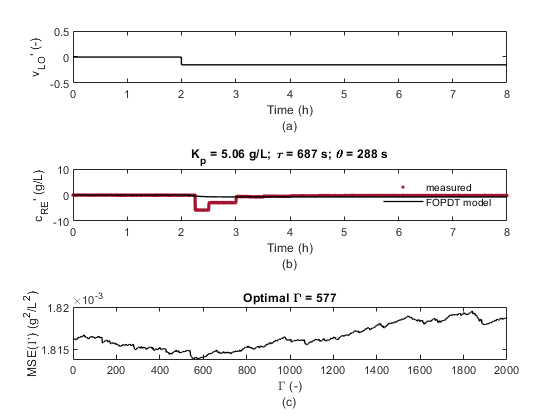

fig = figure(4);

% plot vLO
tlo = tiledlayout(fig, 3,1);
ax1 = nexttile(tlo,1);
plot(vLO_step.timeH, vLO_step.vLO_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("v_{LO}' (-)");
xlim([0 vLO_step.FOPDT_timeH_cRE(end)]);
ylim([-0.5 0.5]);

% plot cRE measured
ax2 = nexttile(tlo,2);
plot(vLO_step.timeH, vLO_step.cRE_prime, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(vLO_step.FOPDT_timeH_cRE, vLO_step.FOPDT_fit_cRE, 'k-', 'LineWidth', 1);
hold off
vLO_step.cRE_title = sprintf('K_p = %.2f g/L; \\tau = %.0f s; \\theta = %.0f s', vLO_step.opt_Kp_cRE, vLO_step.opt_tau_cRE, vLO_step.opt_theta_cRE);
title(vLO_step.cRE_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{RE}' (g/L)");
xlim([0 vLO_step.FOPDT_timeH_cRE(end)]);
ylim([-10 10]);

% plot MSE
ax3 = nexttile(tlo,3);
plot([0:gamma_max], vLO_step.MSE_cRE, 'k-', 'LineWidth', 1);
vLO_step.cRE_MSE_title = sprintf('Optimal \\Gamma = %.0f', vLO_step.opt_gamma_cRE);
title(vLO_step.cRE_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
ylabel("MSE(\Gamma) (g^{2}/L^{2})");
xlim([0 gamma_max]);

% save figure
print('controller_tuning/output/feedback/vLO_step_cRE_model', '-dpng', '-r600');